# Actividad 1.12

Modelo cinemático de piernas

Angel Estrada Centeno - A01732584

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 3]);
H2=SE3(rotz(0), [1 0 0]);
H3=SE3(roty(0), [1 0 0]);
H4=SE3(rotz(0), [1 0 0])

H20=H1*H2;
H30= H20*H3;
H40= H30*H4; %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1 2 3];
y=[0 0 0 0 0];
z=[0 3 3 3 3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H30, H40,'rgb','axis', [-1 6 -1 6 -1 6])
  disp(H40)


Resultado

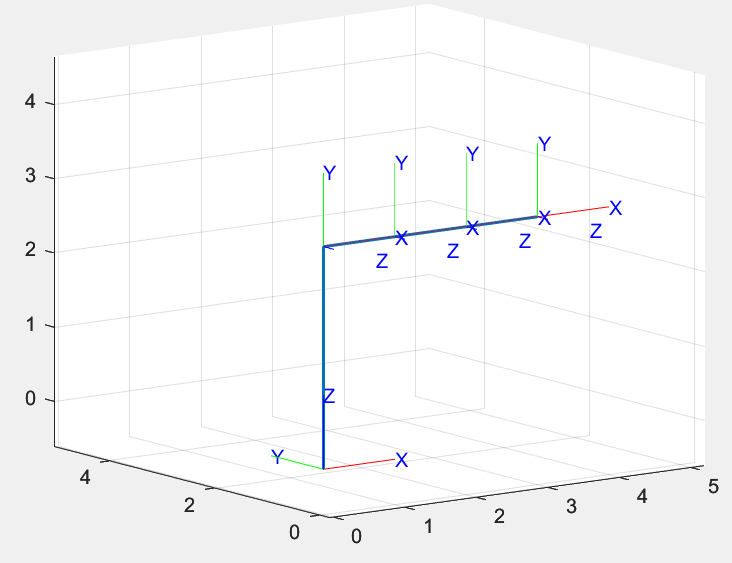

Ejercicio 2

 

H3 = 
         1         0         0        -2
         0    0.9990   -0.0457         0
         0    0.0457    0.9990         0
         0         0         0         1


 

H30 = 
    0.9981   -0.0535    0.0298     1.004
    0.0548    0.9975   -0.0441   -0.1096
   -0.0274    0.0457    0.9986   0.05482
         0         0         0         1


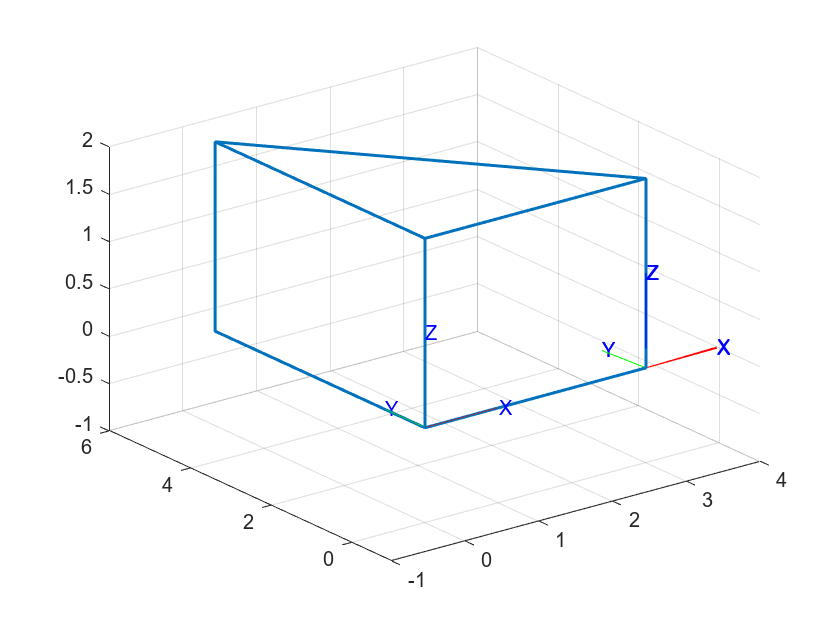

%Limpieza de pantalla
clear all
close all

clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(rotz(pi/2), [0 2 0]);
H3=SE3(rotz(-pi/2), [0 -2 0]);
H4=SE3(roty(pi/2), [0 0 0]);
H5=SE3(rotz(pi/2), [0 0 1]);
H6=SE3(rotz(0), [0 0 1]);

%Matriz de transformación homogenea global de 3 a 0 
H20=H1*H2;
H30= H20*H3;
H40= H30*H4; 
H50= H40*H5;
H60= H50*H6;

%Coordenadas de la estructura de translación y rotación
x=[0 0 0 2 4];
y=[0 0 0 0 0];
z=[0 2 4 4 4];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H30, H40,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H40, H50,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H50, H60,'rgb','axis', [-1 6 -1 6 -1 6])

  disp(H60)
  disp(H6)


Resultado

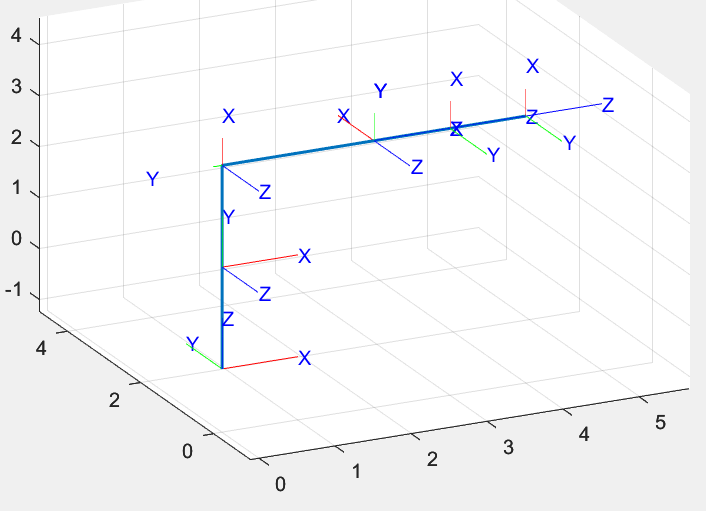

Ejercicio 3

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(0), [2 0 0]);
H2=SE3(rotz(0), [0 0 -4]);
H3=SE3(rotz(0), [0 2 0]);
H4=SE3(roty(0), [0 1 0]);

%Matriz de transformación homogenea global de 3 a 0 
H20=H1*H2;
H30= H20*H3;
H40= H30*H4; 

%Coordenadas de la estructura de translación y rotación
x=[0 2 2 2 2];
y=[0 0 0 2 3];
z=[0 0 -4 -4 -4];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H30, H40,'rgb','axis', [-1 6 -1 6 -1 6])


  disp(H40)
  disp(H4)


Resultado